# **IO641 & IO642 - PROFIBUS Loopback**

The IO641 and IO642 are PROFIBUS modules to connect real-time target machines to industrial equipment. The IO641 is a PROFIBUS Master module that is used to communicate with field-level devices such as motor controllers and sensors. The IO642 is a PROFIBUS Slave module that is used to communicate with devices on the control and process level such as programmable logic controllers. The modules handle the complete data exchange between the real-time application and the connected devices. The data exchange is processed via a dual-port memory. Each module acts as one PROFIBUS station exclusively.

PROFIBUS communication typically takes place between one PROFIBUS Master and multiple PROFIBUS Slaves. In this example, one master (IO641) communicates with one slave (IO642), installed in the same machine. The modules are configured to exchange generic values.

The IO641 requires a configuration file (included with this example). The file is created with SYCON.net, a software tool from Hilscher.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO641 and one IO642 installed

- PROFIBUS cable

The IO641 requires a configuration file. This file comes with the example model and does not have to be created. However, the SYCON.net project is also included in the example and can be used to recreate the configuration file. The module help documentation and the SYCON documentation explain how to use SYCON.net, which is free of charge. Find the download link in the Additional References section below.

### Test Setup

PROFIBUS is a serial fieldbus protocol based on RS-485 for electrical transmissions. Use a cable as defined in the IO641 pin mapping documentation to connect the IO641 with the IO642.

The configuration file (*.nxd) for the IO641 is automatically packed into the real-time application by the build process and unpacked during the initialization of the real-time application on the target.

## Initialize and Open the Simulink Model

 
% Sample time
Ts = 0.001;

% Open Simulink model
modelName = 'sgMdl_IO641_IO642_PROFIBUSLoopback';
open_system(modelName);

### Model Description

The model sets up the communication for both the IO641 and IO642. When starting the model, the [IO641 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io641_setup) block loads the corresponding configuration file onto the I/O module. The IO642 is entirely configured by the [IO642 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io642) block. The Receive and Send blocks are used to exchange data.

The IO642 is configured to send 11 bytes to the IO641. Within this payload, the data is structured as follows:

- Constant signal of type int16

- Counter signal of type uint32

- Sine wave of type single

- Pulse signal of type uint8

The model illustrates how to use [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) blocks to pack the signals into one byte array to be processed by the Send block. [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) blocks are used to extract the signals from the byte array that the Receive block outputs.

The IO641 is configured to send 15 bytes to the IO642. Within this payload, the data is structured as follows:

- Constant signal of type int8

- Counter signal of type uint16

- Sine wave of type double

- Pulse signal of type int32

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Wait until connection is established
pause(5);

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,2);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('S2M_Counter');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Pulse');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('S2M_Sine');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('S2M_Constant');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Counter');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Pulse');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('M2S_Sine');
plotOnSubPlot(s,2,2,true);
s = sdiLatestRun.getSignalsByName('M2S_Constant');
plotOnSubPlot(s,2,2,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(1,2,'AllRange',[0,10,-110,110]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,10,-10,110]);
Simulink.sdi.setSubplotLimits(2,2,'AllRange',[0,10,-110,110]);


### Check the Results

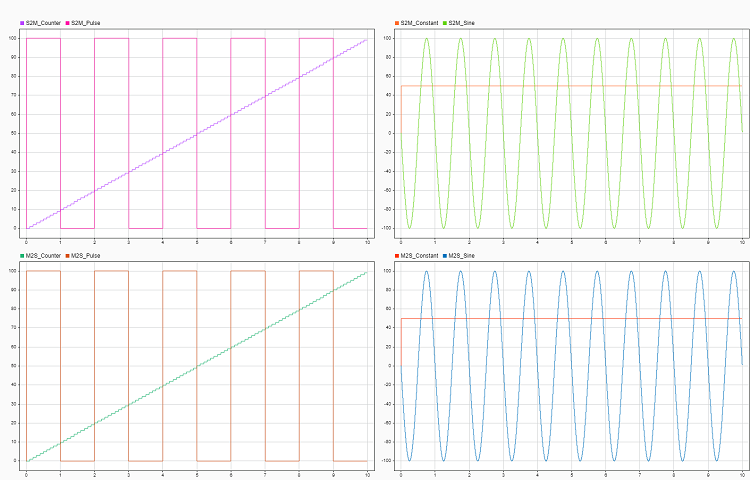

## Additional References

- [IO641 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io641)

- [IO642 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io642)